clear all
load("data\longitudinal_data")
load("data\mass_properties")


**Współczynniki masowe kalkulacje**

% I_yy_CG = I_YY_b

I_YY_b = Iyy + Mass* ((x_CG-x_AC_WB(4))^2)

I_YY_b = 7.9655e+06

**Wspolczynniki do macierzy I równania**

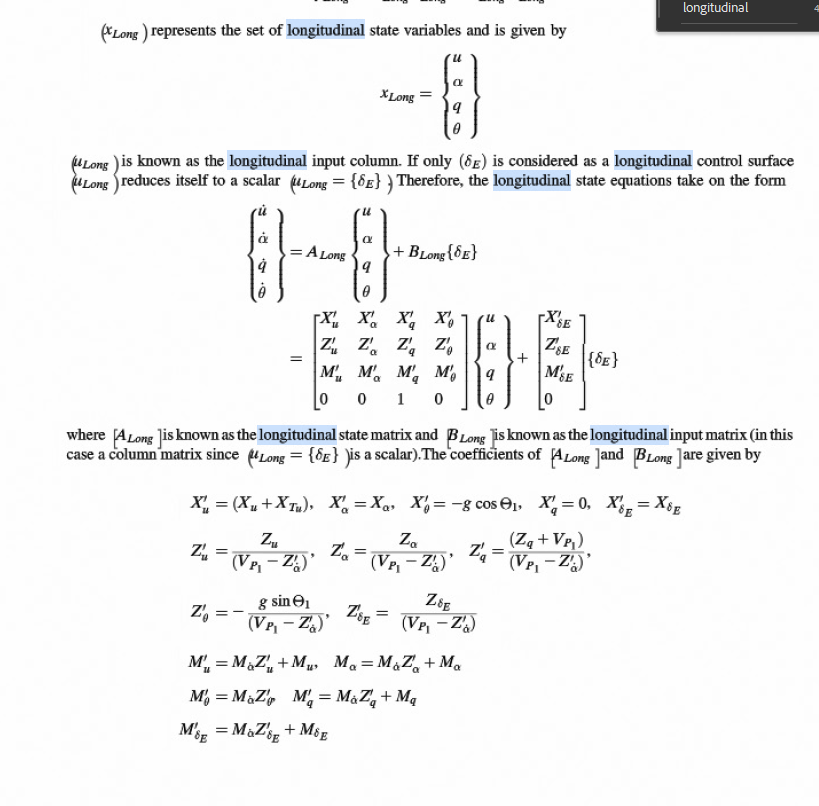

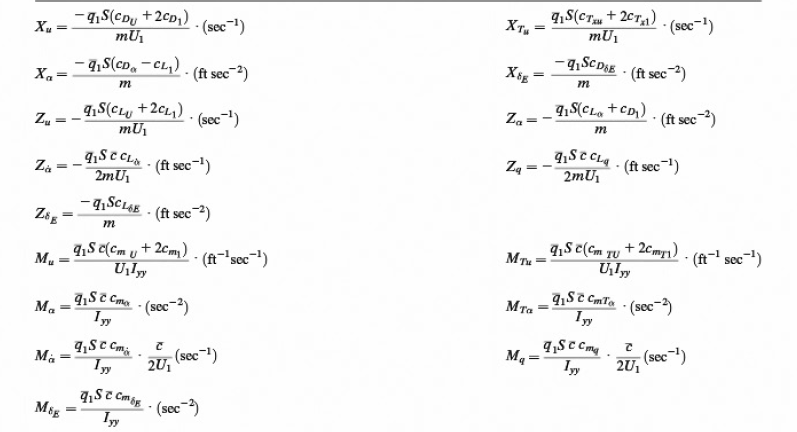

**%%%%%%%%%%%%%%%%%%%%    X   %%%%%%%%%%%%%%%%%%%%%%%%%**

**X'u**

X_u = (-dynamic_pressure(2, 4)*S*(C_Du+(2*C_D1(2, 4))))/ (Mass* Vp1(2, 4))

X_u = -0.0063

X_tu = (dynamic_pressure(2, 4)*S*(C_xTu(2, 4)+2*C_xT1(2, 4)))/(Mass*Vp1(2, 4))

X_tu = -0.0027

dX_u = X_u + X_tu

dX_u = -0.0090

**X'_alpha**

% dX_a = X_a
dX_a = (-dynamic_pressure(2, 4)*S*(C_Da(2, 4)-C_L1(2, 4)))/Mass

dX_a = 16.6938

**X'_theta**

theta_1 = alfa_1(2, 4)

theta_1 = 0.0581

dX_theta = -gravity_acceleration(1)*cos(theta_1)

dX_theta = -32.1157

**X'q**

dX_q = 0

dX_q = 0

**X'delta_e**

% dX_delta_e = X_delta_e
dX_delta_e = -(dynamic_pressure(2, 4)*S*C_Ddelta_E)/Mass

dX_delta_e = 0

**%%%%%%%%%%%%%%%%%%%%    Z   %%%%%%%%%%%%%%%%%%%%%%%%%**

**Z'alpha_dot**

Z_a_dot = (-dynamic_pressure(2, 4)*S*MAC*C_La_dot(4))/(2*Mass*Vp1(2, 4))

Z_a_dot = -2.4311

%dZ_a_dot = Z_a_dot/Vp1(2, 4)
dZ_a_dot = Z_a_dot %uwaga jedna opcja z dwóch

dZ_a_dot = -2.4311

**Z'alpha**

Z_a = (-dynamic_pressure(2, 4)*S*(C_La(4)+C_D1(2, 4)))/Mass

Z_a = -432.2953

dZ_a = Z_a/(Vp1(2, 4) - dZ_a_dot)

dZ_a = -0.6922

**Z'u**

Z_u = ((-dynamic_pressure(2, 4))*S*(C_Lu(2, 4)+2*C_L1(2, 4)))/(Mass*Vp1(2, 4))

Z_u = -0.1325

dZ_u = Z_u/(Vp1(2, 4) - dZ_a_dot)

dZ_u = -2.1222e-04

**Z'q**

Zq = -(dynamic_pressure(2, 4)*S*MAC*C_Lq(4))/(2*Mass*Vp1(2, 4))

Zq = -11.2176

dZ_q = (Zq + Vp1(2, 4))/(Vp1(2, 4) - dZ_a_dot)

dZ_q = 0.9781

**Z'theta**

dZ_theta = -(gravity_acceleration(2)*sin(theta_1))/(Vp1(2, 4) - dZ_a_dot)

dZ_theta = -0.0030

**Z'delta_e**

Z_delta_e = -(dynamic_pressure(2, 4)*S*c_Ldelta_E(4))/Mass

Z_delta_e = -25.7538

dZ_delta_e = Z_delta_e/(Vp1(2, 4)-dZ_a_dot)

dZ_delta_e = -0.0412

**%%%%%%%%%%%%%%%%%%%%    M   %%%%%%%%%%%%%%%%%%%%%%%%%**

**M'a**

M_a_dot = (dynamic_pressure(2, 4)*S*(MAC^2)*C_m_alpha_dot(4))/(2*I_YY_b*Vp1(2, 4))

M_a_dot = -0.2003

M_a = (dynamic_pressure(2 ,4)*S*MAC*C_ma(4))/I_YY_b

M_a = -1.6743

dMa = M_a_dot*dZ_a+M_a

dMa = -1.5356

**M'u**

Mu = (dynamic_pressure(2, 4)*S*MAC*(C_mu(2 ,4)+(2*C_m1)))/(I_YY_b*Vp1(2 ,4))

Mu = -5.7673e-05

dMu = M_a_dot*dZ_u+Mu

dMu = -1.5173e-05

**M'delta_E**

M_delta_E = (dynamic_pressure(2, 4)*S*MAC*C_mdelta_E(4))/I_YY_b

M_delta_E = -1.8033

dM_delta_E = M_a_dot*dZ_delta_e+M_delta_E

dM_delta_E = -1.7950

**M'q**

M_q = ((dynamic_pressure(2, 4)*S*MAC*C_mq(4))/Iyy)*(MAC/(2*Vp1(2, 4)))

M_q = -0.6030

dMq = M_a_dot * dZ_a + M_q

dMq = -0.4644

**M'theta**

dM_theta = M_a_dot*dZ_theta

dM_theta = 5.9932e-04

**Wspolczynniki do macierzy II równania**

**Z''_a**

ddZa = dZ_a*Vp1(2, 4)-gravity_acceleration(1)*sin(theta_1)

ddZa = -432.4816

**Z''_u**

ddZu = dZ_u*Vp1(2, 4)

ddZu = -0.1320

**Z''_q**

ddZq = (dZ_q-1)*Vp1(2, 4)

ddZq = -13.5955

**Z''_theta**

ddZ_theta = dZ_theta*Vp1(2, 4) + gravity_acceleration(1)*sin(theta_1)

ddZ_theta = 0.0073

**Z''_delta_E**

ddZ_delta_E = dZ_delta_e*Vp1(2, 4)

ddZ_delta_E = -25.6535

**%%%%%%%%%%%%%%%%%%%%    MACIERZE   %%%%%%%%%%%%%%%%%%%%%%%%%**

**A**

A = [dX_u dX_a dX_q dX_theta;
    dZ_u dZ_a dZ_q dZ_theta;
    dMu dMa dMq dM_theta;
    0 0 1 0]

A =    -0.0090   16.6938         0  -32.1157
   -0.0002   -0.6922    0.9781   -0.0030
   -0.0000   -1.5356   -0.4644    0.0006
         0         0    1.0000         0


**B**

B = [dX_delta_e;
    dZ_delta_e;
    dM_delta_E;
    0]

B =          0
   -0.0412
   -1.7950
         0


**C**

C = [ddZa ddZu ddZq ddZ_theta;
    1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1]

C =  -432.4816   -0.1320  -13.5955    0.0073
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


**D**

D = [ddZ_delta_E;
    0;
    0;
    0;
    0]

D =   -25.6535
         0
         0
         0
         0


**%%%%%%%%%%%%%%%%%%%%    SIŁOWNIK   %%%%%%%%%%%%%%%%%%%%%%%%%**

c_E = 2

c_E = 2


A_act = [dX_u dX_a dX_q dX_theta 0;
    dZ_u dZ_a dZ_q dZ_theta 0;
    dMu dMa dMq dM_theta 0;
    0 0 1 0 0;
    0 0 0 0 -c_E]

A_act =    -0.0090   16.6938         0  -32.1157         0
   -0.0002   -0.6922    0.9781   -0.0030         0
   -0.0000   -1.5356   -0.4644    0.0006         0
         0         0    1.0000         0         0
         0         0         0         0   -2.0000



B_act = [dX_delta_e 0;
    dZ_delta_e 0;
    dM_delta_E 0;
    0 0;
    0 c_E]

B_act =          0         0
   -0.0412         0
   -1.7950         0
         0         0
         0    2.0000



C_act = [ddZa ddZu ddZq ddZ_theta 0;
    1 0 0 0 0;
    0 1 0 0 0;
    0 0 1 0 0;
    0 0 0 1 0;
    0 0 0 0 1;
    ]

C_act =  -432.4816   -0.1320  -13.5955    0.0073         0
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000



D_act = [ddZ_delta_E 0;
    0 0;
    0 0;
    0 0;
    0 0;
    0 0]

D_act =   -25.6535         0
         0         0
         0         0
         0         0
         0         0
         0         0


**%%%%%%%%%%%%%%%%%%%%    TRANSMITANCJA   %%%%%%%%%%%%%%%%%%%%%%%%%**

M_Ta = (dynamic_pressure(2, 4)*S*MAC*C_mTa)/I_YY_b

M_Ta = 0

M_TU = (dynamic_pressure(2, 4)*S*MAC*(C_mTu(2, 4)+2*C_mT1))/(I_YY_b*Vp1(2, 4))

M_TU = -1.0554e-05


Au = dX_delta_e*(Vp1(2, 4)-Z_a_dot)

Au = 0

Bu = -dX_delta_e*((Vp1(2, 4)-Z_a_dot)*M_q+Z_a+M_a_dot*(Vp1(2, 4)+Z_a))+Z_delta_e*dX_a

Bu = -429.9290

Cu = dX_delta_e*(M_q*Z_a+M_a_dot*gravity_acceleration(2)*sin(theta_1)-(M_a+M_Ta)*(Vp1(2, 4)+Zq))

Cu = 0

Du = gravity_acceleration(1)*sin(theta_1)*dX_delta_e*(M_a+M_Ta)-gravity_acceleration(1)*cos(theta_1)*Z_delta_e*(M_a+M_Ta)+M_delta_E*(gravity_acceleration(2)*cos(theta_1)*Z_a-gravity_acceleration(1)*sin(theta_1)*dX_a)

Du = 2.3708e+04


Aa = Z_delta_e

Aa = -25.7538

Ba = dX_delta_e * Z_u - Z_delta_e*((X_u+X_tu)+M_q)+M_delta_E*(Zq+Vp1(2, 4))

Ba = -1.1174e+03

Ca = dX_delta_e*((Zq+Vp1(2, 4))*(Mu+M_TU)-M_q*Z_u)+Z_delta_e*M_q*(X_u+X_tu)-M_delta_E*(gravity_acceleration(1)*sin(theta_1)+(Zq+Vp1(2, 4))*(X_u+X_tu))

Ca = -6.7307

Da = Z_delta_e*M_a_dot+M_delta_E*(Vp1(2, 4)-Z_a_dot)

Da = -1.1211e+03


At = Z_delta_e*M_a_dot+M_delta_E*(Vp1(2, 4) - Z_a_dot)

At = -1.1211e+03

Bt = dX_delta_e*(Z_u*M_a_dot+(Vp1(2, 4)-Z_a_dot)*(Mu+M_TU))+Z_delta_e*((M_a+M_Ta)*(X_u+X_tu)+dX_a*(Mu+M_TU))-M_delta_E*((Vp1(2, 4)-Z_a_dot)*(X_u+X_tu)-Z_a)

Bt = 769.0170

Ct = dX_delta_e*((M_a+M_Ta)*Z_u-(Mu+M_TU)*Z_a)-Z_delta_e*((M_a+M_Ta)*(X_u+X_tu)+dX_a*(Mu+M_TU))+M_delta_E*((X_u+X_tu)*Z_a-dX_a*Z_u)

Ct = -10.6781


A1 = Vp1(2, 4) - Z_a_dot

A1 = 624.5411

B1 = -(Vp1(2, 4) - Z_a_dot)*(X_u+X_tu+M_q)-Z_a-M_a_dot*(Zq+Vp1(2, 4))

B1 = 936.8860

C1 = (X_u+X_tu)*(M_q*(Vp1(2, 4) - Z_a_dot)+Z_a+M_a_dot*(Vp1(2, 4) - Z_a_dot))+M_q*Z_a-Z_u*dX_a+M_a_dot*gravity_acceleration(1)*sin(theta_1) - (M_a+M_Ta)*(Vp1(2, 4)+Zq)

C1 = 1.2937e+03

D1 = gravity_acceleration(1)*sin(theta_1)*((M_a+M_Ta)-M_a_dot*(X_u+X_tu))+gravity_acceleration(1)*cos(theta_1)*(M_a_dot*Z_u+(Mu+M_TU)*(Vp1(2, 4) - Z_a_dot)) - dX_a *(Mu+M_TU)*(Zq+Vp1(2, 4))+Z_u*dX_a*M_q+(X_u+X_tu)*((M_a+M_Ta)*(Zq+Vp1(2, 4)) - M_q*Z_a)

D1 = 9.9862

E1 = gravity_acceleration(1)*cos(theta_1)*(Z_u*(M_a+M_Ta)-Z_a*(Mu+M_TU))+gravity_acceleration(1)*sin(theta_1)*((Mu+M_TU)*dX_a-(X_u+X_tu)*(M_a+M_Ta))

E1 = 6.1490


D1_dash_roots = roots([A1 B1 C1 D1 E1])

D1_dash_roots =   -0.7479 + 1.2251i
  -0.7479 - 1.2251i
  -0.0021 + 0.0691i
  -0.0021 - 0.0691i


plot(D1_dash_roots, '.', 'MarkerSize', 10)
xlim([-1., 0.1])
damp(D1_dash_roots)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -7.48e-01 + 1.23e+00i     5.21e-01       1.44e+00          1.34e+00    
 -7.48e-01 - 1.23e+00i     5.21e-01       1.44e+00          1.34e+00    
 -2.15e-03 + 6.91e-02i     3.10e-02       6.91e-02          4.66e+02    
 -2.15e-03 - 6.91e-02i     3.10e-02       6.91e-02          4.66e+02    


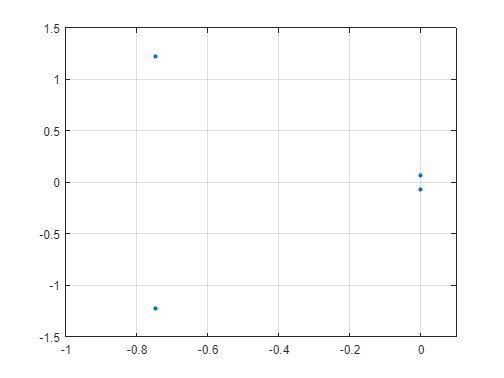




grid on


n_a = (dynamic_pressure(2, 4)*C_La(4)*S)/Weight

n_a = 13.3735

**%%%%%%%%%%%%%%%%%%%% układ stabilizacji %%%%%%%%%%%%%%%%%%%%%%%%**

st ={'u', 'alfa', 'q', 'theta'}

st = 1×4 cell array
    {'u'}    {'alfa'}    {'q'}    {'theta'}


in = {'delta_e'}

in = 1×1 cell array
    {'delta_e'}


out = {'a_z', 'u', 'alfa', 'q', 'theta'}

out = 1×5 cell array
    {'a_z'}    {'u'}    {'alfa'}    {'q'}    {'theta'}


M = ss(A, B, C, D, 'statename', st, 'inputname', in, 'outputname', out)

M =
 
  A = 
                   u        alfa           q       theta
   u       -0.009042       16.69           0      -32.12
   alfa   -0.0002122     -0.6922      0.9781   -0.002993
   q      -1.517e-05      -1.536     -0.4644   0.0005993
   theta           0           0           1           0
 
  B = 
           delta_e
   u             0
   alfa   -0.04124
   q        -1.795
   theta         0
 
  C = 
                 u      alfa         q     theta
   a_z      -432.5    -0.132     -13.6  0.007275
   u             1         0         0         0
   alfa          0         1         0         0
   q             0         0         1         0
   theta         0         0         0         1
 
  D = 
          delta_e
   a_z     -25.65
   u            0
   alfa         0
   q            0
   theta        0
 
Continuous-time state-space model.




%obserwowalność
Ob = obsv(A, C)

Ob = 1.0e+04 *

   -0.0432   -0.0000   -0.0014    0.0000
    0.0001         0         0         0
         0    0.0001         0         0
         0         0    0.0001         0
         0         0         0    0.0001
    0.0004   -0.7199    0.0006    1.3889
   -0.0000    0.0017         0   -0.0032
   -0.0000   -0.0001    0.0001   -0.0000
   -0.0000   -0.0002   -0.0000    0.0000
         0         0    0.0001         0


unobsv = length(M.A) - rank(Ob)

unobsv = 0


%sterowalność
Co =ctrb(M)

Co =          0   -0.6884   28.8205    5.6311
   -0.0412   -1.7273    2.0784    0.7386
   -1.7950    0.8969    2.2349   -4.2294
         0   -1.7950    0.8969    2.2349


unco = length(M.A) - rank(Co)

unco = 0



ObM = obsv(M)

ObM = 1.0e+04 *

   -0.0432   -0.0000   -0.0014    0.0000
    0.0001         0         0         0
         0    0.0001         0         0
         0         0    0.0001         0
         0         0         0    0.0001
    0.0004   -0.7199    0.0006    1.3889
   -0.0000    0.0017         0   -0.0032
   -0.0000   -0.0001    0.0001   -0.0000
   -0.0000   -0.0002   -0.0000    0.0000
         0         0    0.0001         0


r = rank(ObM)

r = 4



M11 = M('q', 'delta_e')

M11 =
 
  A = 
                   u        alfa           q       theta
   u       -0.009042       16.69           0      -32.12
   alfa   -0.0002122     -0.6922      0.9781   -0.002993
   q      -1.517e-05      -1.536     -0.4644   0.0005993
   theta           0           0           1           0
 
  B = 
           delta_e
   u             0
   alfa   -0.04124
   q        -1.795
   theta         0
 
  C = 
          u   alfa      q  theta
   q      0      0      1      0
 
  D = 
      delta_e
   q        0
 
Continuous-time state-space model.


stability =isstable(M11)

stability = logical
   1



ObM11 = obsv(M11)

ObM11 =          0         0    1.0000         0
   -0.0000   -1.5356   -0.4644    0.0006
    0.0003    1.7758   -1.2858    0.0048
   -0.0004    0.7509    2.3389   -0.0168


r112 = rank(ObM11)

r112 = 4

r112-length(ObM11)

ans = 0

r11 = rank(ObM11)

r11 = 4


G11 = tf(-M11)

G11 =
 
  From input "delta_e" to output "q":
    1.795 s^3 + 1.195 s^2 + 0.01701 s + 3.191e-19
  -------------------------------------------------
  s^4 + 1.166 s^3 + 1.837 s^2 + 0.01288 s + 0.01008
 
Continuous-time transfer function.
Model Properties


stability11 = isstable(G11)

stability11 = logical
   1




k = 1.44 %wzmocnienie

k = 1.4400


G22 = feedback(G11, k)

G22 =
 
  From input "delta_e" to output "q":
   1.795 s^3 + 1.195 s^2 + 0.01701 s + 3.191e-19
  ------------------------------------------------
  s^4 + 3.75 s^3 + 3.558 s^2 + 0.03737 s + 0.01008
 
Continuous-time transfer function.
Model Properties


stability22 = isstable(G22)

stability22 = logical
   1


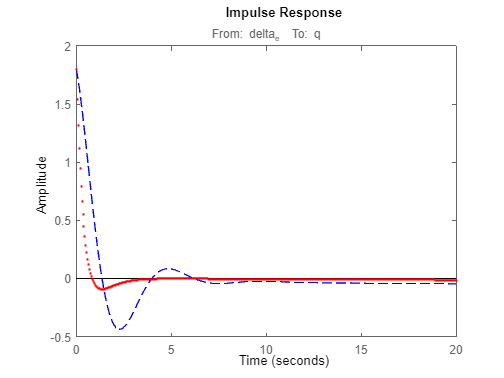


impulse(G11, 'b--', G22, 'r.', 20)

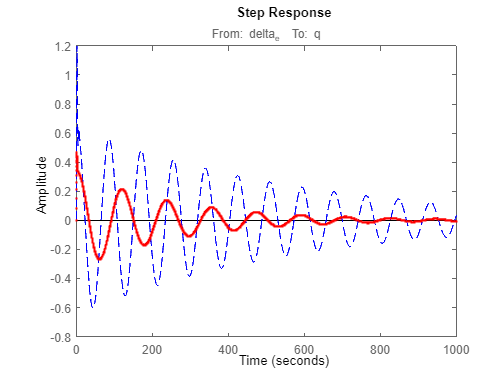

step(G11, 'b--', G22, 'r.', 1000)

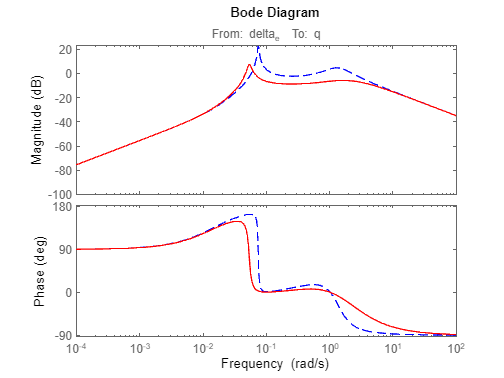

bode(G11, 'b--', G22, 'r-')



%bode(G11)

%damp(G11)
damp(G22)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.78e-03 + 5.33e-02i     7.07e-02       5.35e-02         2.64e+02    
 -3.78e-03 - 5.33e-02i     7.07e-02       5.35e-02         2.64e+02    
 -1.87e+00 + 1.57e-01i     9.96e-01       1.88e+00         5.34e-01    
 -1.87e+00 - 1.57e-01i     9.96e-01       1.88e+00         5.34e-01    


%%%%%%%%% ocena wlasnosci pilotazowych %%%%%%%%%%%%%%%%%%

w = damp(G22)

w =     0.0535
    0.0535
    1.8781
    1.8781



n_a

n_a = 13.3735

%short period
w_sp = w(3) %2 poziom

w_sp = 1.8781

zeta_sp = 9.96e-01

zeta_sp = 0.9960

%faza A >>2,002 1 poziom >>1.49 2 i 3 poziom
%B >>1.08 1 poziom >>0.7477 2 i 3 poziom
%C >>1.484 1 poziom >>1.13 2 i 3 poziom

%phugoid
w_ph = w(1)

w_ph = 0.0535

zeta_ph = 7.07e-02   %1 poziom

zeta_ph = 0.0707



CAP = (w_sp^2)/n_a

CAP = 0.2637

%A 2 poziom
%B 1 poziom
%C 1 poziom





%%%%%%%%%%%%%%% układ stabilizacji %%%%%%%%%%%%%%%%%%
st3 ={'u', 'alfa', 'q', 'theta', 'delta_E'}

st3 = 1×5 cell array
    {'u'}    {'alfa'}    {'q'}    {'theta'}    {'delta_E'}


in3 = {'delta_e, delta_PC_E'}

in3 = 1×1 cell array
    {'delta_e, delta_PC_E'}


out3 = {'a_z', 'u', 'alfa', 'q', 'theta', 'delta_E'}

out3 = 1×6 cell array
    {'a_z'}    {'u'}    {'alfa'}    {'q'}    {'theta'}    {'delta_E'}


M_act = ss(A_act, B_act, C_act, D_act, 'statename', st3, 'inputname', in3, 'outputname', out3)

M_act =
 
  A = 
                     u        alfa           q       theta     delta_E
   u         -0.009042       16.69           0      -32.12           0
   alfa     -0.0002122     -0.6922      0.9781   -0.002993           0
   q        -1.517e-05      -1.536     -0.4644   0.0005993           0
   theta             0           0           1           0           0
   delta_E           0           0           0           0          -2
 
  B = 
            delta_e, del  delta_e, del
   u                   0             0
   alfa         -0.04124             0
   q              -1.795             0
   theta               0             0
   delta_E             0             2
 
  C = 
                   u      alfa         q     theta   delta_E
   a_z        -432.5    -0.132     -13.6  0.007275         0
   u               1         0         0         0         0
   alfa            0         1         0         0         0
   q               0         0         1         0         0


isstable(M_act)

ans = logical
   1


Ob_act = 1.0e+04 *

   -0.0432   -0.0000   -0.0014    0.0000         0
    0.0001         0         0         0         0
         0    0.0001         0         0         0
         0         0    0.0001         0         0
         0         0         0    0.0001         0
         0         0         0         0    0.0001
    0.0004   -0.7199    0.0006    1.3889         0
   -0.0000    0.0017         0   -0.0032         0
   -0.0000   -0.0001    0.0001   -0.0000         0
   -0.0000   -0.0002   -0.0000    0.0000         0


unobsv_act = 1

Co_act =          0         0   -0.6884         0   28.8205         0    5.6311         0  -59.4956         0
   -0.0412         0   -1.7273         0    2.0784         0    0.7386         0   -4.6561         0
   -1.7950         0    0.8969         0    2.2349         0   -4.2294         0    0.8312         0
         0         0   -1.7950         0    0.8969         0    2.2349         0   -4.2294         0
         0    2.0000         0   -4.0000         0    8.0000         0  -16.0000         0   32.0000


unco_act = 1